clear;
close;
clc;

J1 = 1;
J2 = 1;
A0 = [zeros(2) eye(2); zeros(2,4)]

a0 =      0     0     1     0
     0     0     0     1
     0     0     0     0
     0     0     0     0


Ak = [zeros(2,4) ; [-1 1;1 -1] zeros(2)]

ak =      0     0     0     0
     0     0     0     0
    -1     1     0     0
     1    -1     0     0


Af = [zeros(2,4) ; zeros(2) [-1 1;1 -1]]

af =      0     0     0     0
     0     0     0     0
     0     0    -1     1
     0     0     1    -1


E0 = diag([1 1 J1 J2])

e0 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


B = [0 0;0 0;1 1;0 0] % b = [b1 b2]

b =      0     0
     0     0
     1     1
     0     0


C = [0 1 0 0;1 0 0 0;0 1 0 0;0 0 0 0] % c = [c1;c2]

c =      0     1     0     0
     1     0     0     0
     0     1     0     0
     0     0     0     0


D = [0 0;0 0;0 0;0 1]

d =      0     0
     0     0
     0     0
     0     1


% Range of parameter variation
pv = pvec('box',[0.09 0.4 ; 0.0038 0.04])

pv =     1.0000    0.0900    0.4000         0         0
    2.0000    0.0038    0.0400         0         0


% Parameter-dependent (uncertain) plant
P = psys(pv,[ ltisys(A0,B,C,D,E0) , ...
ltisys(Ak,0*B,0*C,0*D,0) , ...
ltisys(Af,0*B,0*C,0*D,0) ])

P =      -Inf + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   4.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   4.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   4.0000 + 0.0000i   1.0000 + 0.0000i   0.0900 + 0.0000i   0.4000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   2.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.00

region = lmireg



Select a region among the following:

h)   Half-plane
d)   Disk 
c)   Conic sector 
e)   Ellipsoid 
p)   Parabola 
s)   Horizontal strip 
m)   Matrix description of the LMI region
q)   Quit

region =

     []



gopt = msfsyn(P,[1 1],[0 0 1 0],region)


 Optimization of the H-infinity performance G :
 ----------------------------------------------

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3
     4
     5
     6                 177.568879
     7                  59.307250
     8                  48.790234
     9                  48.790234
    10                  22.122123
    11                  22.122123
    12                  22.122123
    13                   9.351697
    14                   9.351697
    15                   9.351697
    16                   1.947069
    17                   1.947069
    18                   0.991814
    19                   0.991814
    20                   0.991814
    21                   0.211476
    22                   0.198960
    23                   0.198960
    24                   0.097095
    25                   0.068074
    26                   0.068074
    27                   0.022749
   

gopt = 7.4457e-04

gopt = [];
h2opt = [];
region = lmireg



Select a region among the following:

h)   Half-plane
d)   Disk 
c)   Conic sector 
e)   Ellipsoid 
p)   Parabola 
s)   Horizontal strip 
m)   Matrix description of the LMI region
q)   Quit


Select a region among the following:

h)   Half-plane
d)   Disk 
c)   Conic sector 
e)   Ellipsoid 
p)   Parabola 
s)   Horizontal strip 
m)   Matrix description of the LMI region
q)   Quit


region =    0.2000 + 1.0000i   1.0000 + 0.0000i


for g = [0.01, 0.1, 0.2, 0.5]
    [gopt(end+1),h2opt(end+1),K,Pcl] = msfsyn(P,[1 1],[g 0 0 1],region)
end


 Optimization of   0.000 * G^2 +  1.000 * H^2 :
 ----------------------------------------------

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22
    23
***                 new lower bound:    -9.541492
    24
***                 new lower bound:    -8.945226
    25
    26
    27
    28
    29
    30
    31
    32
    33
    34
    35                  30.883430
    36                  29.123239
***                 new lower bound:     8.347900
    37                  29.123239
***                 new lower bound:    12.548323
    38                  27.636505
***                 new lower bound:    18.170884
    39                  27.439933
***                 new lower bound:    19.857547
    40                  27.148428
***                 new lower bound:    22.0

gopt = 0.0100

h2opt = 5.1432

K = 1.0e+03 *

   -0.2283   -0.1018   -0.0356   -2.0897


Pcl = 1.0e+03 *

      -Inf         0         0         0    0.0010         0         0    0.0040         0         0         0    0.0010         0         0    0.0040         0         0         0    0.0010         0         0    0.0040         0         0         0    0.0010         0         0    0.0040
    0.0010         0         0         0         0    0.0010         0         0         0         0         0         0    0.0010         0         0         0         0         0         0    0.0010         0         0         0         0         0         0    0.0010         0         0
    0.0040         0   -0.2284   -0.1017   -0.0356   -2.0897    0.0010         0         0   -0.2287   -0.1014   -0.0356   -2.0897    0.0010         0         0   -0.2284   -0.1017   -0.0356   -2.0897    0.0010         0         0   -0.2287   -0.1014   -0.0356   -2.0897    0.0010         0
    0.0040         0    0.0001   -0.0001    0.0000   -0.0000         0         0         0    0.0004   -0.0004


 Optimization of   0.000 * G^2 +  1.000 * H^2 :
 ----------------------------------------------

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21                   9.124707
    22                   8.725621
    23                   8.725621
***                 new lower bound:    -1.687999
    24                   8.236033
***                 new lower bound:     2.445682
    25                   8.104570
***                 new lower bound:     3.501873
    26                   7.961328
***                 new lower bound:     4.559698
    27                   7.872891
***                 new lower bound:     5.094244
    28                   7.804108
***                 new lower bound:     5.543488
    29                   7.804108
***                 new lower bound:    

gopt =     0.0100    0.1000


h2opt =     5.1432    2.6978


K =   -28.5838   -2.5679   -8.8782 -133.3805


Pcl =       -Inf         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000
    1.0000         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0
    4.0000         0  -28.6738   -2.4779   -8.8820 -133.3767    1.0000         0         0  -28.9838   -2.1679   -8.8820 -133.3767    1.0000         0         0  -28.6738   -2.4779   -8.9182 -133.3405    1.0000         0         0  -28.9838   -2.1679   -8.9182 -133.3405    1.0000         0
    4.0000         0    0.0900   -0.0900    0.0038   -0.0038         0         0         0    0.4000   -0.4000    0.0038 


 Optimization of   0.000 * G^2 +  1.000 * H^2 :
 ----------------------------------------------

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19                   7.282946
    20                   6.653914
    21                   6.653914
    22                   6.178300
***                 new lower bound:     1.498364
    23                   6.178300
***                 new lower bound:     2.411071
    24                   5.824922
***                 new lower bound:     3.570214
    25                   5.775497
***                 new lower bound:     3.958084
    26                   5.702183
***                 new lower bound:     4.434801
    27                   5.673746
***                 new lower bound:     4.650262
    28                   5.652065
***                 

gopt =     0.0100    0.1000    0.2000


h2opt =     5.1432    2.6978    2.3521


K =   -17.2607   -0.2287   -6.5153  -71.3885


Pcl =       -Inf         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000
    1.0000         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0
    4.0000         0  -17.3507   -0.1387   -6.5191  -71.3847    1.0000         0         0  -17.6607    0.1713   -6.5191  -71.3847    1.0000         0         0  -17.3507   -0.1387   -6.5553  -71.3485    1.0000         0         0  -17.6607    0.1713   -6.5553  -71.3485    1.0000         0
    4.0000         0    0.0900   -0.0900    0.0038   -0.0038         0         0         0    0.4000   -0.4000    0.0038 


 Optimization of   0.000 * G^2 +  1.000 * H^2 :
 ----------------------------------------------

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18                   6.257129
    19                   5.485654
    20                   5.485654
    21                   5.284808
    22                   5.284808
***                 new lower bound:     0.279663
    23                   4.740214
***                 new lower bound:     1.198536
    24                   4.659939
***                 new lower bound:     1.799674
    25                   4.596308
***                 new lower bound:     2.478764
    26                   4.491511
***                 new lower bound:     2.892343
    27                   4.450790
***                 new lower bound:     3.142913
    28                   4.

gopt =     0.0100    0.1000    0.2000    0.5000


h2opt =     5.1432    2.6978    2.3521    2.0507


K =   -10.0439    1.9912   -4.7785  -34.4555


Pcl =       -Inf         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000
    1.0000         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0
    4.0000         0  -10.1339    2.0812   -4.7823  -34.4517    1.0000         0         0  -10.4439    2.3912   -4.7823  -34.4517    1.0000         0         0  -10.1339    2.0812   -4.8185  -34.4155    1.0000         0         0  -10.4439    2.3912   -4.8185  -34.4155    1.0000         0
    4.0000         0    0.0900   -0.0900    0.0038   -0.0038         0         0         0    0.4000   -0.4000    0.0038 

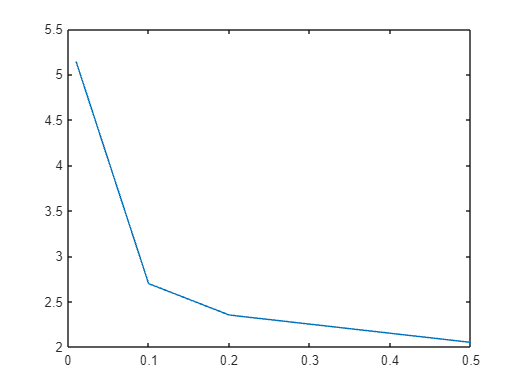

plot(gopt, h2opt)